%https://www.mathworks.com/help/robotics/ug/avoid-obstacles-using-reinforcement-learning-for-mobile-robots.html
%A lot of inspiration from above link, but tailored to our own needs. It
%fits a lot of the simulation problems like robotics and things like that,
%whereas we use a different model, different parameters, etc.
load exampleMaps simpleMap 
load exampleHelperOfficeAreaMap office_area_map
mapMatrix = simpleMap;
mapScale = 1;

scanAngles = [-3*pi/8:pi/8:3*pi/8];
maxRange = 12;
testRange = 15;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

angles  = 180:-1.5:-178.5;
angles = deg2rad(angles)';

maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution,maxLidarRange);

slamAlg.LoopClosureThreshold = 200;
slamAlg.LoopClosureSearchRadius = 3;
controlRate = rateControl(10);

scans = [0 0];
%scans = mat2cell(scans)

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 17;
initY = 15;
initTheta = pi/2;

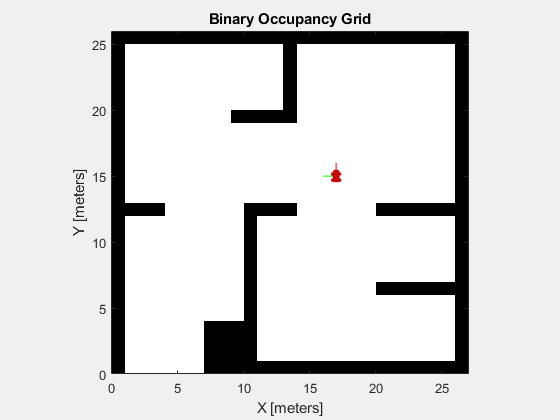

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 100;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

open_system(mdl)

% obsInfo = rlNumericSpec([numel(scanAngles) 1],...
%     "LowerLimit",zeros(numel(scanAngles),1),...
%     "UpperLimit",ones(numel(scanAngles),1)*maxRange);
obsInfo = rlNumericSpec([31 31 1]);
numObservations = obsInfo.Dimension(1);

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "Off";

% statePath = [
%     featureInputLayer(numObservations, "Normalization","none","Name","State")
%     fullyConnectedLayer(50,"Name","CriticStateFC1")
%     reluLayer("Name","CriticRelu1")
%     fullyConnectedLayer(25,"Name","CriticStateFC2")];
statePath = [
    imageInputLayer([31 31 1],"Normalization","none","Name","State")

    convolution2dLayer(3,8,'Padding', 'same')
    %batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

criticOptions = rlOptimizerOptions("LearnRate",5e-3,"L2RegularizationFactor",5e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action",UseDevice="gpu");

% actorNetwork = [
%     featureInputLayer(numObservations,"Normalization","none","Name","State")
%     fullyConnectedLayer(50,"Name","actorFC1")
%     reluLayer("Name","actorReLU1")
%     fullyConnectedLayer(50, "Name","actorFC2")
%     reluLayer("Name","actorReLU2")
%     fullyConnectedLayer(2, "Name","actorFC3")
%     tanhLayer("Name","Action")];
actorNetwork = [
    imageInputLayer([31 31 1],"Normalization","none")

    convolution2dLayer(3,8,'Padding', 'same')
    %batchNormalizationLayer
    reluLayer("Name","actorReLU1")
    
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    %batchNormalizationLayer
    reluLayer("Name","actorReLU2")
    
    fullyConnectedLayer(50, "Name","actorFC2")
    
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",5e-4,"L2RegularizationFactor",5e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo,UseDevice="gpu");

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
%open_system(mdl + "/Agent")

maxEpisodes = 5000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",400, ...
    "Verbose", true, ...
    "Plots","training-progress", ...
    "StopOnError","off");

doTraining = true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

Episode:   1/5000 | Episode reward:  -115.56 | Episode steps:  164 | Average reward:  -115.56 | Step Count:  164 | Episode Q0:   -23.51


Episode:   2/5000 | Episode reward:  -107.73 | Episode steps:  156 | Average reward:  -111.64 | Step Count:  320 | Episode Q0:    -9.54


Episode:   3/5000 | Episode reward:  -245.35 | Episode steps:  336 | Average reward:  -156.21 | Step Count:  656 | Episode Q0:   -37.53


Episode:   4/5000 | Episode reward:  -197.35 | Episode steps:  307 | Average reward:  -166.50 | Step Count:  963 | Episode Q0:   -28.60


Episode:   5/5000 | Episode reward:  -166.78 | Episode steps:  276 | Average reward:  -166.55 | Step Count: 1239 | Episode Q0:   -25.71


Episode:   6/5000 | Episode reward:  -170.12 | Episode steps:  269 | Average reward:  -167.15 | Step Count: 1508 | Episode Q0:   -33.50


Episode:   7/5000 | Episode reward:   -87.21 | Episode steps:  109 | Average reward:  -155.73 | Step Count: 1617 | Episode Q0:   -26.75


Episode:   8/5000 | Episode reward:  -597.28 | Episode steps: 1000 | Average reward:  -210.92 | Step Count: 2617 | Episode Q0:   -29.68


Episode:   9/5000 | Episode reward:    -9.38 | Episode steps:   11 | Average reward:  -188.53 | Step Count: 2628 | Episode Q0:   -16.26


Episode:  10/5000 | Episode reward:  -389.63 | Episode steps: 1000 | Average reward:  -208.64 | Step Count: 3628 | Episode Q0:    -8.62


Episode:  11/5000 | Episode reward:   -96.66 | Episode steps:  156 | Average reward:  -198.46 | Step Count: 3784 | Episode Q0:   -14.28


Episode:  12/5000 | Episode reward:  -248.13 | Episode steps:  390 | Average reward:  -202.60 | Step Count: 4174 | Episode Q0:   -36.93


Episode:  13/5000 | Episode reward:   -40.47 | Episode steps:   46 | Average reward:  -190.13 | Step Count: 4220 | Episode Q0:   -38.45


Episode:  14/5000 | Episode reward:  -118.26 | Episode steps:  172 | Average reward:  -184.99 | Step Count: 4392 | Episode Q0:   -24.36


Episode:  15/5000 | Episode reward:   -44.11 | Episode steps:   52 | Average reward:  -175.60 | Step Count: 4444 | Episode Q0:   -39.58


Episode:  16/5000 | Episode reward:  -244.55 | Episode steps:  508 | Average reward:  -179.91 | Step Count: 4952 | Episode Q0:   -26.48


Episode:  17/5000 | Episode reward:  -240.74 | Episode steps:  519 | Average reward:  -183.49 | Step Count: 5471 | Episode Q0:    -7.40


Episode:  18/5000 | Episode reward:   -50.70 | Episode steps:   59 | Average reward:  -176.11 | Step Count: 5530 | Episode Q0:   -40.77


Episode:  19/5000 | Episode reward:  -473.99 | Episode steps: 1000 | Average reward:  -191.79 | Step Count: 6530 | Episode Q0:   -40.81


Episode:  20/5000 | Episode reward:   -13.76 | Episode steps:   16 | Average reward:  -182.89 | Step Count: 6546 | Episode Q0:   -12.26


Episode:  21/5000 | Episode reward:   -36.45 | Episode steps:   44 | Average reward:  -175.91 | Step Count: 6590 | Episode Q0:   -37.41


Episode:  22/5000 | Episode reward:  -148.04 | Episode steps:  277 | Average reward:  -174.65 | Step Count: 6867 | Episode Q0:   -40.11


Episode:  23/5000 | Episode reward:  -606.21 | Episode steps: 1000 | Average reward:  -193.41 | Step Count: 7867 | Episode Q0:   -37.44


Episode:  24/5000 | Episode reward:  -171.89 | Episode steps:  336 | Average reward:  -192.51 | Step Count: 8203 | Episode Q0:   -39.92


Episode:  25/5000 | Episode reward:  -451.09 | Episode steps: 1000 | Average reward:  -202.86 | Step Count: 9203 | Episode Q0:   -28.21


Episode:  26/5000 | Episode reward:  -369.80 | Episode steps: 1000 | Average reward:  -209.28 | Step Count: 10203 | Episode Q0:   -27.66


Episode:  27/5000 | Episode reward:  -457.59 | Episode steps: 1000 | Average reward:  -218.48 | Step Count: 11203 | Episode Q0:   -22.43


Episode:  28/5000 | Episode reward:  -304.80 | Episode steps: 1000 | Average reward:  -221.56 | Step Count: 12203 | Episode Q0:   -23.79


Episode:  29/5000 | Episode reward:  -325.75 | Episode steps: 1000 | Average reward:  -225.15 | Step Count: 13203 | Episode Q0:   -19.75


Episode:  30/5000 | Episode reward:  -390.91 | Episode steps:  419 | Average reward:  -230.68 | Step Count: 13622 | Episode Q0:   -32.16


Episode:  31/5000 | Episode reward:   -13.10 | Episode steps:   15 | Average reward:  -223.66 | Step Count: 13637 | Episode Q0:   -12.40


Episode:  32/5000 | Episode reward:  -235.74 | Episode steps:  502 | Average reward:  -224.04 | Step Count: 14139 | Episode Q0:   -29.68


Episode:  33/5000 | Episode reward:  -202.14 | Episode steps:  404 | Average reward:  -223.37 | Step Count: 14543 | Episode Q0:   -45.29


Episode:  34/5000 | Episode reward:  -474.43 | Episode steps: 1000 | Average reward:  -230.76 | Step Count: 15543 | Episode Q0:    -9.18


Episode:  35/5000 | Episode reward:   -15.37 | Episode steps:   17 | Average reward:  -224.60 | Step Count: 15560 | Episode Q0:   -14.04


Episode:  36/5000 | Episode reward:  -421.69 | Episode steps: 1000 | Average reward:  -230.08 | Step Count: 16560 | Episode Q0:     1.73


Episode:  37/5000 | Episode reward:  -301.62 | Episode steps: 1000 | Average reward:  -232.01 | Step Count: 17560 | Episode Q0:   -44.99


Episode:  38/5000 | Episode reward:  -499.88 | Episode steps: 1000 | Average reward:  -239.06 | Step Count: 18560 | Episode Q0:   -44.38


Episode:  39/5000 | Episode reward:   -23.09 | Episode steps:   27 | Average reward:  -233.52 | Step Count: 18587 | Episode Q0:   -46.42


Episode:  40/5000 | Episode reward:  -708.27 | Episode steps: 1000 | Average reward:  -245.39 | Step Count: 19587 | Episode Q0:   -31.93


Episode:  41/5000 | Episode reward:  -391.90 | Episode steps: 1000 | Average reward:  -248.96 | Step Count: 20587 | Episode Q0:   -32.03


Error using rl.train.SeriesTrainer/run
An error occurred while running the simulation for model 'exampleHelperAvoidObstaclesMobileRobot' with the
following RL agent blocks:
 	exampleHelperAvoidObstaclesMobileRobot/Agent

Error in rl.train.TrainingManager/train (line 456)
            run(trainer);

Error in 

%out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");
out = sim("exampleHelperAvoidObstaclesMobileRobot.slx","StopTime","100");

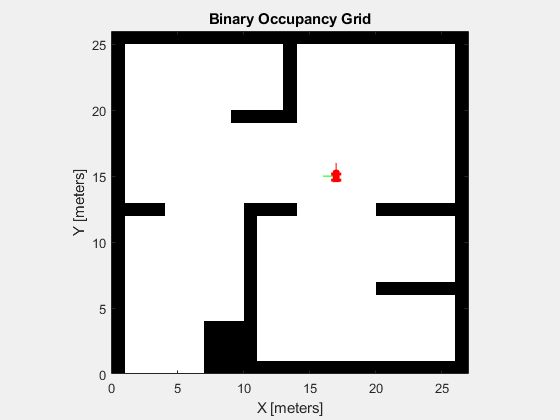

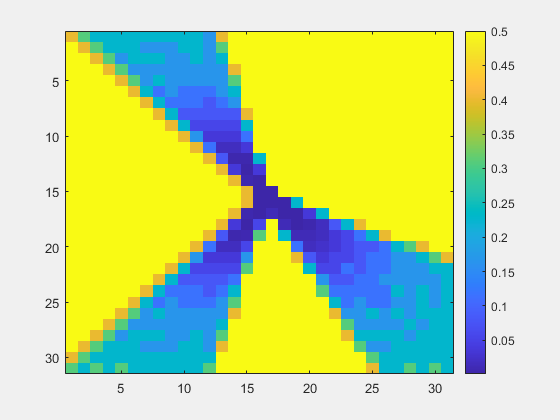

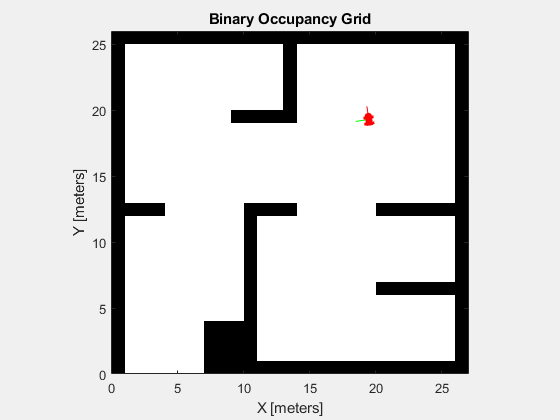

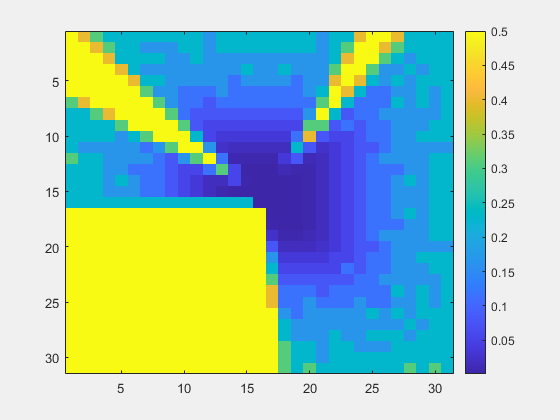

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

figTwo = figure("Name","myMap");
set(figTwo, "Visible","on");
axTwo = axes(figTwo);

for i = 1:5:size(out.range,1)
    u = out.pose(i,:);
    r = out.range(i,:)';
    lolwtf = out.occMatOut;
    %r = out.range(:,:,i)
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    myPlot(axTwo, out.occMatOut(:,:,i));
end

figure
imagesc(out.occMatOut(:,:,1))
figure
imagesc(out.occMatOut(:,:,2))
figure
imagesc(out.occMatOut(:,:,3))

figure(1)
for imageI = 1:12
    subplot(4,3,imageI)
    imagesc(out.occMatOut(:,:,imageI*10))
    axis off;
    title(imageI)
end

figure
imagesc(out.occMatOut(:,:,end))

f = figure();
fh.windowState = "maximized"
for imageI = 1:50
    subplot(5,10,imageI)
    imagesc(out.occMatOut(:,:,end-imageI))
    axis off;
    title(imageI)
end

% figTwo = figure("Name","myMap");
% set(figTwo, "Visible","on");
% axTwo = axes(figTwo);

% writerObj = VideoWriter('examplemy.avi');
% writerObj.FrameRate = 30;
% open(writerObj);

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);
figTwo = figure("Name","myMap");
set(figTwo, "Visible","on");
axTwo = axes(figTwo);


for i = i:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    %frame = getframe;
    %writeVideo(writerObj,frame);
    %myPlot(axTwo, out.occMatOut(:,:,i));
end
%close(writerObj)


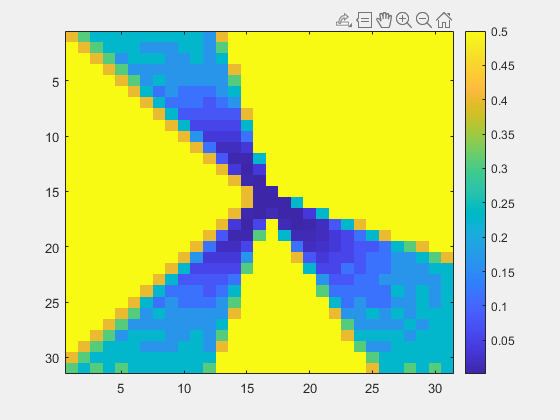

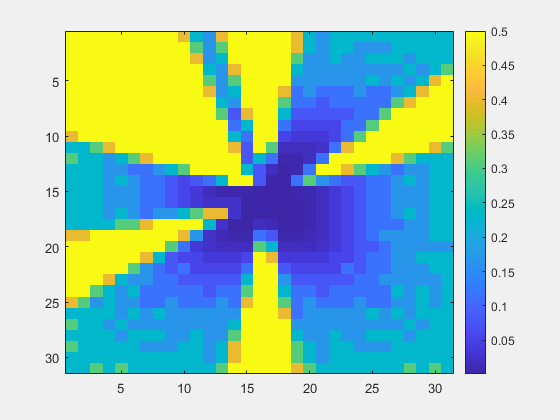

figTwo = figure("Name","myMap");
set(figTwo, "Visible","on");
axTwo = axes(figTwo);

writerObj = VideoWriter('newrewardmidtrainmapanotherex.avi');
writerObj.FrameRate = 30;
open(writerObj);

for i = 1:5:size(out.range,1)
    u = out.pose(i,:);
    r = out.range(i,:)';
    lolwtf = out.occMatOut;
    %r = out.range(:,:,i)
    %exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    myPlot(axTwo, out.occMatOut(:,:,i));
    frame = getframe;
    writeVideo(writerObj,frame);
end

close(writerObj)

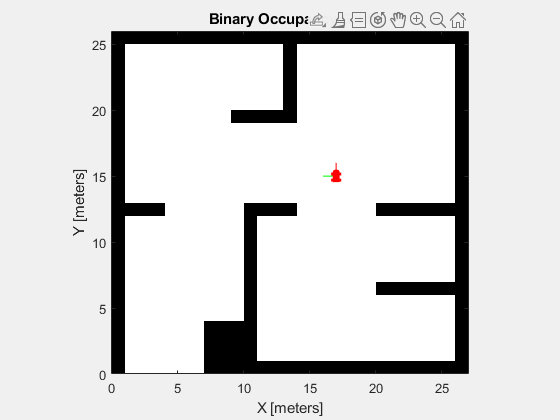

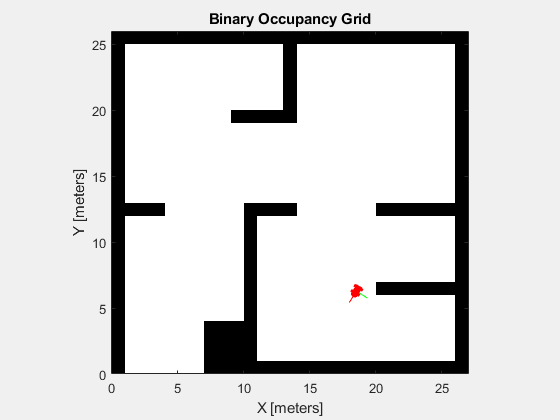

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

writerObj = VideoWriter('newrewardmidtrainbotguyanotherex.avi');
writerObj.FrameRate = 30;
open(writerObj);


for i = 1:5:size(out.range,1)
    u = out.pose(i,:);
    r = out.range(i,:)';
    lolwtf = out.occMatOut;
    %r = out.range(:,:,i)
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    frame = getframe;
    writeVideo(writerObj,frame);
end

close(writerObj)